Nielsen & Kiørboe:

 - potential clearance rate [um^3/s]

 - (volume) specific clearance rate   [s^-1] hvor clearance rate er divideret med volumen af organismen

NUM

- specific clearance rate (alphaF) [l/day/cell mass]

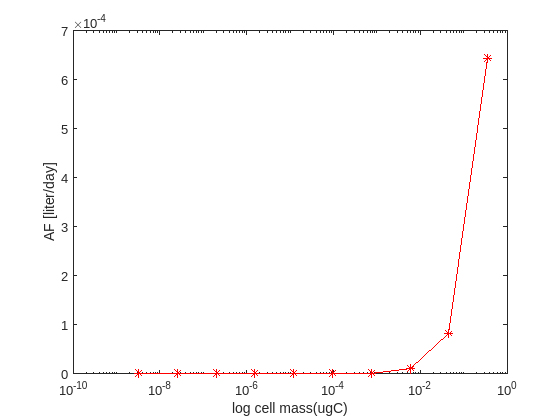

m=[3.25126467845392e-09, 2.54401988814737e-08, 1.99062144468872e-07, 1.55760328546027e-06, 1.21877919146803e-05, 9.53659209261690e-05, 0.000746210547223221, 0.00583888013012814, 0.0456875359117736, 0.357491657847033]; %[ugC]
alphaF=0.0018; %[liter/day/ugC]

AF=m.*alphaF;
figure
semilogx(m,AF, '*-r'); 
xlabel('log cell mass(ugC)'); 
ylabel('AF [liter/day]')

Vi skal have colume-specific clearance rate så vi omregner massen fra ugC til l:

radius_cell=((3.*m)./(4*pi*(0.6*10^(-6)))).^(1/3); %mass ugC --> radius um
vol_cell=(4/3).*pi.*radius_cell.^3; %um --> um^3

radius_to_vol = 1.0e+05 *

    0.0000    0.0000    0.0000    0.0000    0.0002    0.0016    0.0124    0.0973    0.7615    5.9582


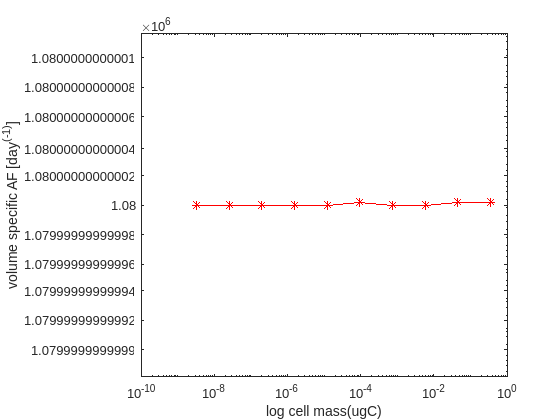

mass_liter=vol.*1e-15; %um^3 --> liter
AF_volume_specific=AF./mass_liter;

figure
loglog(m,AF_volume_specific, '*-r'); 
xlabel('log cell mass(ugC)'); 
ylabel('volume specific AF [day^{(-1)}]')

Hvis vi sammenligner med en med højere alphaF

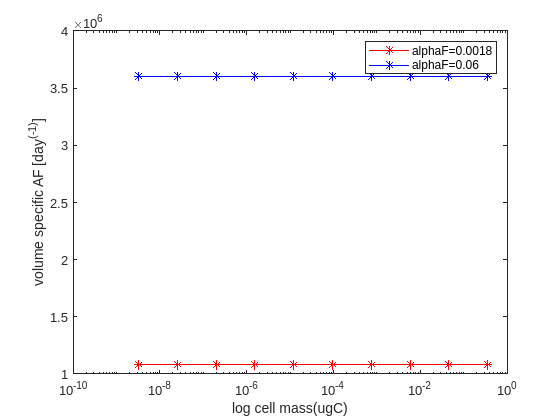

alphaF=0.006; %[liter/day/ugC]
AF=m.*alphaF;
AF_volume_specific2=AF./mass_liter;
figure
semilogx(m,AF_volume_specific, '*-r'); 
hold on
semilogx(m,AF_volume_specific2, '*-b'); 
xlabel('log cell mass(ugC)'); 
ylabel('volume specific AF [day^{(-1)}]')
legend('alphaF=0.0018','alphaF=0.06')

log_specific_encounter_cross_sec=10.^(0.65*log(AF_volume_specific))

log_specific_encounter_cross_sec = 1.0e+09 *

    1.0718    1.0718    1.0718    1.0718    1.0718    1.0718    1.0718    1.0718    1.0718    1.0718
